clear
[audio, Fs] = audioread("peppered_cantina.wav", 'native');
player = audioplayer(audio, Fs);
%play(player)

%appropriate audio
serialized_pep = extract_N_LSB(audio, 8, 2);
%use bits_in_image calculated from earlier to slice what is needed
bytes_in_image = 512*512;
serialized_pep = serialized_pep(1:bytes_in_image)

serialized_pep =      5    20    20    14    17    13     9    14    10    11    11    10     8     6     7     8     2     0     0     2     6     6     1     0     6     6     6     6     7     7     7     7     3     2     2     3     5     8    10    12    14    14    14    13    11     9     7     5     0     1


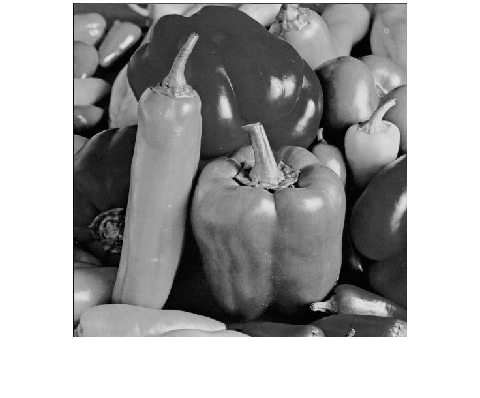

reconstructed_pepper = reshape(uint8(serialized_pep), [512, 512]);
imshow(reconstructed_pepper)

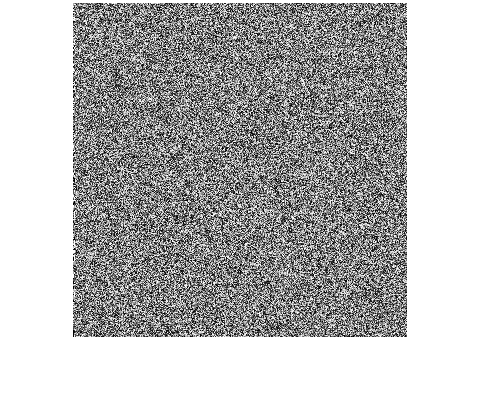


%filtered audio
%this comes from assignment 8, and I've reused much of my code with a
%different sample rate
passband_edge = 700; %Hz
stopband_edge = 1000; %Hz
Fc = 0.5 * (passband_edge + stopband_edge); % Hz
wc_sansPi = 2*(Fc/Fs);
wc = wc_sansPi * pi;
transi_BW = 2*pi* ((stopband_edge-passband_edge)/Fs);
M_min = (12*pi)/transi_BW; %441, good odd length filter

%window it
wc_win = wc;
M = -220:220;
window = blackman(441);
h = sin(wc_win*M)./(pi*M);
h(221) = wc_win/pi;
h_windowed = h .* window';

%filter
filtered_pep = conv(audio,h_windowed, 'same');
serialized_filtered_pep = extract_N_LSB(int16(filtered_pep), 8, 2);
reconstructed_filtered_pep = reshape(uint8(serialized_filtered_pep), [512, 512]);
imshow(reconstructed_filtered_pep)

function [LsbByteArray] = extract_N_LSB(audio,bits,num_LSBs)
    %take the LSB from audio and chunk it into bytes the size of 
    %the bits argument. Do this for N LSBs
    zero_out = repmat('0', 1, 16-num_LSBs);
    one_out = repmat('1', 1, num_LSBs);
    binstr = [zero_out one_out];

    LSBarray = dec2bin(bitand(audio(1:end), typecast(uint16(bin2dec(binstr)), 'int16')));
    %the special case of 8 does not return a full 8 bit binary string, it
    %drops the leading 0. We can send it directly to output
    if num_LSBs == 8
        LsbByteArray = bin2dec(LSBarray)';
    else
        %serialize the array and chop off anything that doesn't fit
        LSBarray = reshape(LSBarray.', 1, []);
        LSBarray = LSBarray(1:floorDiv(length(LSBarray), bits)*bits);
        LSBarray = reshape(LSBarray', bits, []).';
        %convert to a number so we can cast the whole thing to char
        LSBarray = bin2dec(LSBarray)';
        LsbByteArray = LSBarray;
    end
end
